**The simulation involving perturbations of Pol II numbers.**

**For Figure 3e.**

Get the degradation rate per mRNA of WT cells from data.

% Fitting the data with an one-phase exponential decay model
Data_Swaffer2021_time=readmatrix('../Data/Data_Swaffer2022_RNAPdepletion.xlsx','sheet','RNAPdep');
wt_time=Data_Swaffer2021_time(29:56,7);
wt_num=Data_Swaffer2021_time(29:56,8);
k0dep_time=Data_Swaffer2021_time(1:28,7);
k0dep_num=Data_Swaffer2021_time(1:28,8);

% Fitting
[xData, yData] = prepareCurveData( wt_time, wt_num );
ft = fittype( 'exp1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [1.04703713367938 -0.155018577659328];
[fitresult, gof] = fit( xData, yData, ft, opts );
%plot( fitresult, xData, yData );
wt_degco=-fitresult.b

wt_degco = 0.1626

rsquare=gof.rsquare

rsquare = 0.9699

Optimize the basic paramters by minimizing the difference between between the experimental and predicted degradation rates in WT cells 

% Basic paramters
load ../Parameter_determination/Basic_parameters.mat

para0=para_opt;


% Optimization
ftobeopt = @(x)Myoptfun(x,wt_degco,syms_solve);

lb=[   0   0   0   0   0   0   0   0   0   0   0];
ub=[   inf inf inf inf inf inf inf inf inf inf inf];

options = optimoptions('fmincon','UseParallel',true);

Res_temp=fmincon(ftobeopt,para0,[],[],[],[],lb,ub,[],options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



wt_degco_pre=Xcdeplete(Res_temp,syms_solve)

wt_degco_pre = 0.1626

wt_degco

wt_degco = 0.1626


SuqaredErr=ftobeopt(Res_temp)

SuqaredErr = 3.8735e-11


para_opt_v=Res_temp; %The parameters for Pol II depletion

Simulations

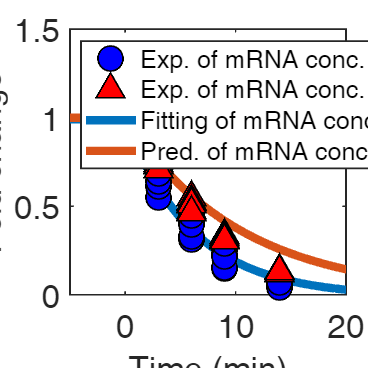

% Numerically solve the homeostatic values
load ../Solve_values/Solve_values.mat % Symbolic solutions
syms_solve=[Xn_pre,Xc_pre,Xp_pre,Yn_pre,Yp_pre];
syms k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv
para_sym=[k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv];
para_num=[para_opt_v,2.8,37.2,5.8262];
%para:[k0 Kx Ky Km am ax ay bm bx Xt Yt]
temp1=double(subs(syms_solve,para_sym,para_num));% Xn Xc Xp Yn Yp
temp1=temp1(~any(temp1<0,2),:);
temp2=[2.8*para_opt_v(7)/para_opt_v(5),37.2*para_opt_v(9)/para_opt_v(8)];% mn mc
y_wt=[temp2,temp1]; %[mn mc Xn Xc Xp Yn Yp]

% Parameters for WT cells
k0=para_opt_v(1);
am=para_opt_v(5);
ax=para_opt_v(6);
ay=para_opt_v(7);
bx=para_opt_v(9);
bm=para_opt_v(8);
Kx=para_opt_v(2);
Km=para_opt_v(4);
Vn=2.8;
Vc=37.2;
Ky=para_opt_v(3);
Xt=para_opt_v(10);
Yt=para_opt_v(11);

mn0=y_wt(1);
mc0=y_wt(2);
Xn0=y_wt(3);
Xc0=y_wt(4);
Xp0=y_wt(5);
Yn0=y_wt(6);
Yp0=y_wt(7);


% Parameters for the monitored gene
mntest0=mn0*0.001;
mctest0=mc0*0.001;
k0test=k0*0.001;

% Simulations for WT cells
Kv=5.8262;

para1=[para_opt_v,Vn,Vc,Kv,k0test];
y_ini=[y_wt,mntest0,mctest0];

tspan=[1:1:10000];
[~,y_tot]=ode15s(@(t,y)diffun(y,para1),tspan,y_ini);
temp1=(y_tot(:,8)+y_tot(:,9))/(Vn+Vc);

y_ini2=y_tot(end,:);
para2=para1;
para2(15)=0;

[~,y_tot2]=ode15s(@(t,y)diffun(y,para2),tspan,y_ini2);
temp2=(y_tot2(:,8)+y_tot2(:,9))/(Vn+Vc);

cmtest_wt=[temp1;temp2];


% Simulations for the cells in which half of Pol II is depleted
Kv=2*5.8262;%deplete half of Pol II

para1=[para_opt_v,Vn,Vc,Kv,k0test];
y_ini=[y_wt,mntest0,mctest0];

tspan=[1:1:10000];
[~,y_tot]=ode15s(@(t,y)diffun(y,para1),tspan,y_ini);
temp1=(y_tot(:,8)+y_tot(:,9))/(Vn+Vc);

y_ini2=y_tot(end,:);
para2=para1;
para2(15)=0;

[~,y_tot2]=ode15s(@(t,y)diffun(y,para2),tspan,y_ini2);
temp2=(y_tot2(:,8)+y_tot2(:,9))/(Vn+Vc);

cmtest_half=[temp1;temp2];


%plot
colors=["#0072BD"
    "#D95319"
    "#EDB120"
    "#7E2F8E"
    "#77AC30"
    "#4DBEEE"
    "#A2142F"
    '#FF0000'
    '#00FF00'
    '#0000FF'
    '#00FFFF'
    '#FF00FF'
    '#FFFF00'
    '#000000'
    '#FFFFFF'];


fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

scale_time=(1:2e4)-1e4-1;
p3=plot(scale_time,cmtest_wt/cmtest_wt(1e4)-0.01,'-', ...
    "LineWidth",5, ...
    "Color",colors(1),...
    "DisplayName","Fitting of mRNA conc. in WT");
hold on
p4=plot(scale_time,cmtest_half/cmtest_half(1e4),'-', ...
    "LineWidth",5, ...
    "Color",colors(2),...
    "DisplayName","Pred. of mRNA conc. after depleting Pol II");
hold on
p1=plot(Data_Swaffer2021_time(29:56,7),Data_Swaffer2021_time(29:56,8), ...
    'o', ...
    "MarkerSize",15, ...
    "MarkerEdgeColor",'black',...
    "LineWidth",1,...
    "MarkerFaceColor",colors(10), ...
    "DisplayName","Exp. of mRNA conc. in WT");
hold on
p2=plot(Data_Swaffer2021_time(1:28,7),Data_Swaffer2021_time(1:28,8), ...
    '^', ...
    "MarkerSize",15, ...
    "MarkerEdgeColor",'black',...
    "LineWidth",1,...
    "MarkerFaceColor",colors(8), ...
    "DisplayName","Exp. of mRNA conc. after depleting Pol II");
hold off
xlim([-5,20])
ylim([0,1.5])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend([p1 p2 p3 p4],"Interpreter","tex","FontSize",15,'Location','northwest')
xlabel('Time (min)','interpreter','tex','FontSize',20);
ylabel('Fold change','interpreter','tex','FontSize',20);

function dydt = diffun(y,para)
%%% Differential equations of the system
%%% monitoring the change of one gene

%y:[mn mc Xn Xc Xp Yn Yp mntest mctest]
mn=y(1);
mc=y(2);
Xn=y(3);
Xc=y(4);
Xp=y(5);
Yn=y(6);
Yp=y(7);
mntest=y(8);
mctest=y(9);

%para:[k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv kntest0]

k0=para(1);
Kx=para(2);
Ky=para(3);
Km=para(4);
am=para(5);
ax=para(6);
ay=para(7);
bm=para(8);
bx=para(9);
%Xt=para(10);
%Yt=para(11);
Vn=para(12);
Vc=para(13);
Kv=para(14);
k0test=para(15);

dydt = zeros(9,1);
%dydt:[dmndt dmcdt dXndt dXcdt dXpdt dYndt dYpdt dmntestdt dmctestdt]

%ODE of the system
kn=(k0*Vn/(Vn+Kv))*(Xp/(Xp+Kx*Vn))*Vn*Km/(Vn*Km+mn)*Yp/(Yp+Ky*Vn);

dydt(1)=kn-am*(Yn/Vn)*mn;
dydt(2)=am*(Yn/Vn)*mn-bm*(Xc/Vc)*mc;
dydt(3)=kn-ax*Xn;
dydt(4)=ax*Xn-bx*Xc;
dydt(5)=bx*Xc-kn;
dydt(6)=kn-ay*Yn;
dydt(7)=ay*Yn-kn;

%ODE of the monitored gene
kntest=(k0test*Vn/(Vn+Kv))*(Xp/(Xp+Kx*Vn))*Vn*Km/(Vn*Km+mn)*Yp/(Yp+Ky*Vn);
dydt(8)=kntest-am*(Yn/Vn)*mntest;%dmntestdt
dydt(9)=am*(Yn/Vn)*mntest-bm*(Xc/Vc)*mctest;%dmctestdt


end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


function [wt_degco_pre]=Xcdeplete(para0,syms_solve)
%%% The function calculating the degradation rate per mRNA.

%Numerically solve the values of molecules in WT cells
syms k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv
para_sym=[k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv];
para_num=[para0,2.8,37.2,5.8262];
%para:[k0 Kx Ky Km am ax ay bm bx Xt Yt]
temp1=double(subs(syms_solve,para_sym,para_num));% Xn Xc Xp Yn Yp
temp1=temp1(~any(temp1<0,2),:);
temp2=[2.8*para0(7)/para0(5),37.2*para0(9)/para0(8)];% mn mc

y_wt=[temp2,temp1];

%degradation rate per mRNA
bm=para0(8);
Vc=37.2;%fL
wt_degco_pre=bm*(y_wt(4)/Vc);

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


function Optobj=Myoptfun(para0,wt_degco,syms_solve)
%%% The function to be optimized.

wt_degco_pre=Xcdeplete(para0,syms_solve);

Optobj=(wt_degco_pre-wt_degco)^2;%squared error

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%




